data = readtable("Results/rndPW_PWIdx/rnd_PW_rnd_PWSltIdx_tti_4_1500.csv")

data = 1500×12 table
    RNTIs_DL    numDLTotal    numDLnew    numReTx_DL    avgMCS_DL    numULTotal    numULnew    numReTx_UL    avgMCS_UL    PulseWidth    PulseWidthSlotIdx    TTI
    ________    __________    ________    __________    _________    __________    ________    __________    _________    __________    _________________    ___

        1           98           79           19            5            90           75           15            5            48              2501            4 
        2          101           85           16            5            94           7

data_tti2 = readtable("Results/rndPW_PWIdx/rnd_PW_rnd_PWSltIdx_tti_2_1500.csv")

data_tti2 = 1500×12 table
    RNTIs_DL    numDLTotal    numDLnew    numReTx_DL    avgMCS_DL    numULTotal    numULnew    numReTx_UL    avgMCS_UL    PulseWidth    PulseWidthSlotIdx    TTI
    ________    __________    ________    __________    _________    __________    ________    __________    _________    __________    _________________    ___

        1          120           71           49            5            95           62           33            5           434              2622            2 
        2          128           72           56            5            89       

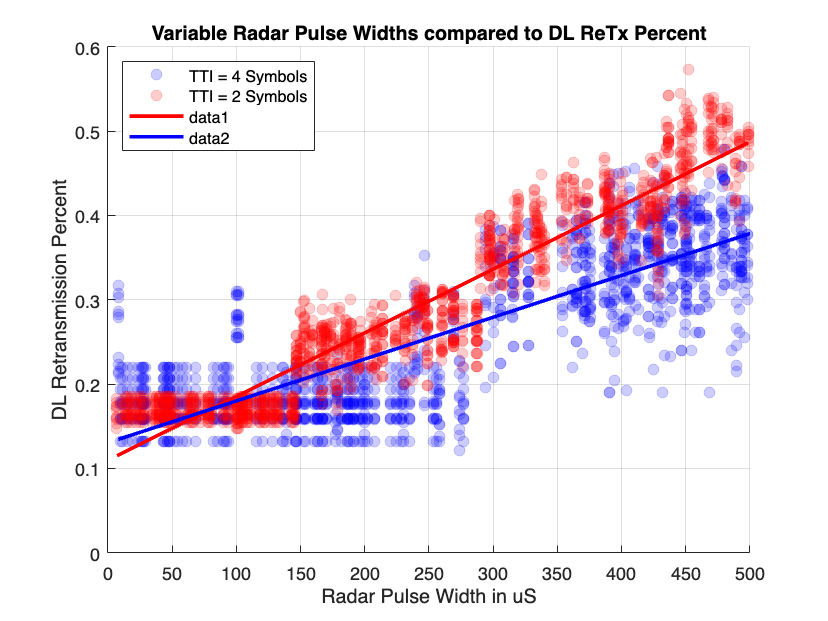

data.ReTxPrcnt = data.numReTx_DL ./ data.numDLTotal;
data_tti2.ReTxPrcnt = data_tti2.numReTx_DL ./ data_tti2.numDLTotal;


% scatter(data.PulseWidth,,'filled')
tti4 = scatter(data.PulseWidth,data.ReTxPrcnt,'MarkerFaceColor','b','MarkerEdgeColor','b',...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
hold on


title('Variable Radar Pulse Widths compared to DL ReTx Percent')
xlabel("Radar Pulse Width in uS")
ylabel('DL Retransmission Percent')
xlim([0 500])
ylim([0 0.6])
grid
lgnd = legend;
lgnd.Location = 'northwest';
tti2 = scatter(data_tti2.PulseWidth,data_tti2.ReTxPrcnt,'MarkerFaceColor','r','MarkerEdgeColor','r',...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
tti2.DisplayName = 'TTI = 2 Symbols';
tti4.DisplayName = 'TTI = 4 Symbols';


% Fit a linear trendline (1st-degree polynomial)
p = polyfit(data_tti2.PulseWidth, data_tti2.ReTxPrcnt, 1); % Linear fit (degree 1)
trendline_y = polyval(p, data_tti2.PulseWidth);
plot(data_tti2.PulseWidth, trendline_y, '-r', 'LineWidth', 2);

p = polyfit(data.PulseWidth, data.ReTxPrcnt, 1); % Linear fit (degree 1)
trendline_y = polyval(p, data.PulseWidth);
plot(data.PulseWidth, trendline_y, '-b', 'LineWidth', 2);

hold off


tti2_t = 143;
tti4_t = 286;

%TTI 2

var(data_tti2.ReTxPrcnt(data_tti2.PulseWidth >= 0 & data_tti2.PulseWidth < tti2_t))

ans = 1.0392e-04

mean(data_tti2.ReTxPrcnt(data_tti2.PulseWidth >= 0 & data_tti2.PulseWidth < tti2_t))

ans = 0.1690


0.00010392

ans = 1.0392e-04

var(data_tti2.ReTxPrcnt(data_tti2.PulseWidth >= tti2_t & data_tti2.PulseWidth < tti4_t))

ans = 0.0012

mean(data_tti2.ReTxPrcnt(data_tti2.PulseWidth >= tti2_t & data_tti2.PulseWidth < tti4_t))

ans = 0.2495


var(data_tti2.ReTxPrcnt(data_tti2.PulseWidth >= tti4_t & data_tti2.PulseWidth < 500))

ans = 0.0041

mean(data_tti2.ReTxPrcnt(data_tti2.PulseWidth >= tti4_t & data_tti2.PulseWidth < 500))

ans = 0.4094




%TTI4
var(data.ReTxPrcnt(data.PulseWidth >= 0 & data.PulseWidth < tti4_t))

ans = 0.0014

mean(data.ReTxPrcnt(data.PulseWidth >= 0 & data.PulseWidth < tti4_t))

ans = 0.1846

var(data.ReTxPrcnt(data.PulseWidth >= tti4_t & data.PulseWidth < 500))

ans = 0.0026